# 遗传算法

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


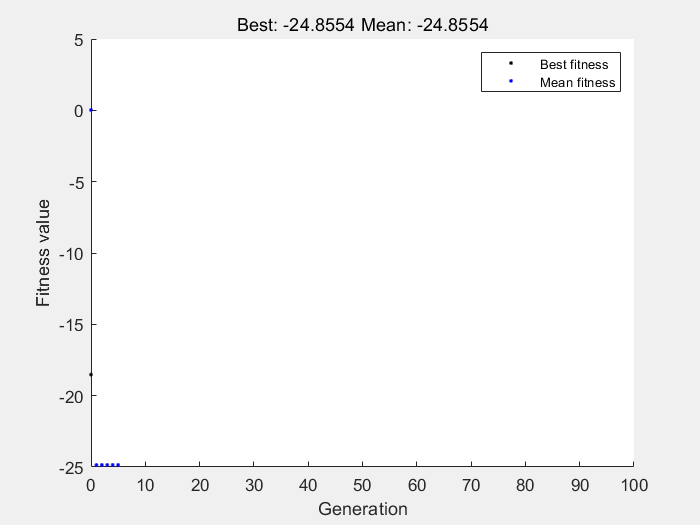

nvars = 1;
A = [];
b = [];
Aeq = [];
beq = [];

x_lb = [];
x_ub = [];

options = optimoptions("ga","PlotFcn","gaplotbestf","HybridFcn","fmincon");
[x, fval, exitflag, output] = ga(@Obj_fun, nvars, A, b, Aeq, beq, x_lb, x_ub, @conditions, options);

fval = -fval;
x, fval

x = 7.8567

fval = 24.8554

## 函数定义

function y = Obj_fun(x)
    y = x + 10 * sin(5 * x) + 7 * cos(4 * x);
    y = -y;
end

function [c, ceq] = conditions(x)
    % 表示 c <= 0, ceq = 0
%     c(1) = x(1)^2 + x(2)^2 + x(3)^2;
%     c(2) = 2*x(1)^2 + x(2)^2;
    c = [];
    ceq = [];
end